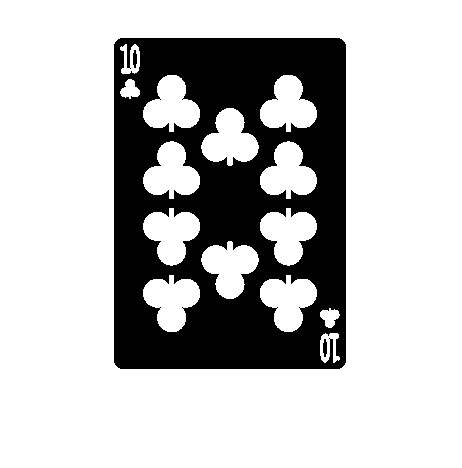

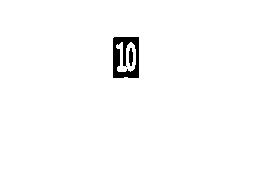

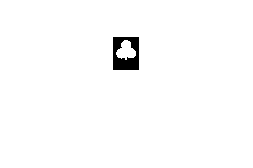

% Change file path here
input = 'C:\Users\Tom\Desktop\School\Lectures\7. Semester\Image Processing\scat_cards\';
dinfo = dir(fullfile(input, '*.png')); 

T = 240;

% Put breakpoint at the end of loop to see each picture result
for i = 1 : length(dinfo)
  thisimage = dinfo(i).name;  % just the name of the image
  file_name = sprintf('%s%s',input,thisimage); % full file name
  data_img = imread(file_name);
  gray = rgb2gray(data_img);
  thresh = gray < T;
  cropped_shape = imcrop(thresh,[5 40 25 32]);
  cropped_num = imcrop(thresh,[5 3 25 40]);
  figure(1),imshow(gray)
  figure(2),imshow(cropped_num)
  figure(3),imshow(cropped_shape)
  figure(4),imshow(data_img  )
  shape = get_shape(cropped_shape, data_img);
  number = get_num(cropped_num);
  card_name = append(number,' ',shape);
  text(70,15,card_name,'Color','red','FontSize',14);

end